Author: **Arjan Gupta**

Due: April 3, 2023

Class: RBE 501

Institution: Worcester Polytechnic Institute

## Preliminary Setup

### Build Denso's HSR robot with Robotics Toolkit

In the prompt of this assignment, we are given the following table.


$$\matrix{
\text{Link}    	& a_i 	& \alpha_i &  d_i & \theta_i  \cr
1			& 205 			& 0	& 220	& \theta_1			\cr
2			& 275 			& 0		& 0	& \theta_2		\cr
3			& 0 			& 0			& d_3 & 0	\cr
4	        & 0 			& 0 		    & 0 & \theta_4					\cr
}$$


To implement this, we first define joint variables.

theta1 = 0;
theta2 = 0;
d3 = 0;
theta4 = 0;

Now, we can import the DH params from the given table.

dhparams = [205   	0   	220   	theta1;
            275	    0       0       theta2;
            0   	0	    d3	    0;
            0       0       0       theta4];

Next, we create a rigid body tree object to build the Denso HSR robot. This is necessary to begin assigning rigid bodies (links) of the robot, to represent moving parts.

denso_robot = rigidBodyTree("DataFormat","column");

We can begin building the robot now. We make sure that the order of the joints is revolute, revolute, prismatic, revolute. This is because, as shown in the information web-page of Denso Robotics, the HSR robot is essentially a SCARA robot with a revolute tool-tip.

As described in the tutorial of the Robotics Toolkit, we need to assign bodies and joints, as shown in the following code.

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','prismatic');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');

We can then set their transforms (this is done by using rows of the DH table we are given). 

setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

Joints also need to be associated with their bodies, as shown in the following code.

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

Finally, bodies can be assigned to the rigid-body tree.

addBody(denso_robot,body1,'base')
addBody(denso_robot,body2,'body1')
addBody(denso_robot,body3,'body2')
addBody(denso_robot,body4,'body3')

We can verify that our robot was built correctly by showing its details.

showdetails(denso_robot)

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


### Show target positions

In the video, the robot picks up the 4 sets of water bottles and moves them to new locations (this sequence is the first 8 moves/goal positions). Then it picks them up again, in a different order, and puts them back in the starting positions (another 8 moves). In the following set of goal positions, we have shown the first 8 positions from the video. For our angles, we have chosen estimated values such that the end-effector lies on the 180 degree arc.

goal_pos = zeros(4,1,8);

The following is the first position of the robot shown in the video, i.e. when the robot picks up the first set of water bottles.

goal_pos(:,:,1) = [deg2rad(0);deg2rad(0);-200;0]; % Goal position 1

Similarly, set the positions where the robot drops off the first set of water bottles,

goal_pos(:,:,2) = [deg2rad(50);deg2rad(15);-200;0]; % Goal position 2

picks up the second set of water bottles,

goal_pos(:,:,3) = [deg2rad(7.5);deg2rad(7.5);-200;0]; % Goal position 3

drops off the second set of water bottles,

goal_pos(:,:,4) = [deg2rad(55);deg2rad(35);-200;0]; % Goal position 4

picks up the third set of water bottles,

goal_pos(:,:,5) = [deg2rad(180);deg2rad(0);-200;0]; % Goal position 5

drops off the third set of water bottles,

goal_pos(:,:,6) = [deg2rad(140);deg2rad(-25);-200;0]; % Goal position 6

picks up the fourth set of water bottles,

goal_pos(:,:,7) = [deg2rad(160);deg2rad(5);-200;0]; % Goal position 7

drops off the fourth set of water bottles,

goal_pos(:,:,8) = [deg2rad(115);deg2rad(-15);-200;0]; % Goal position 8

picks up the third set of water bottles,

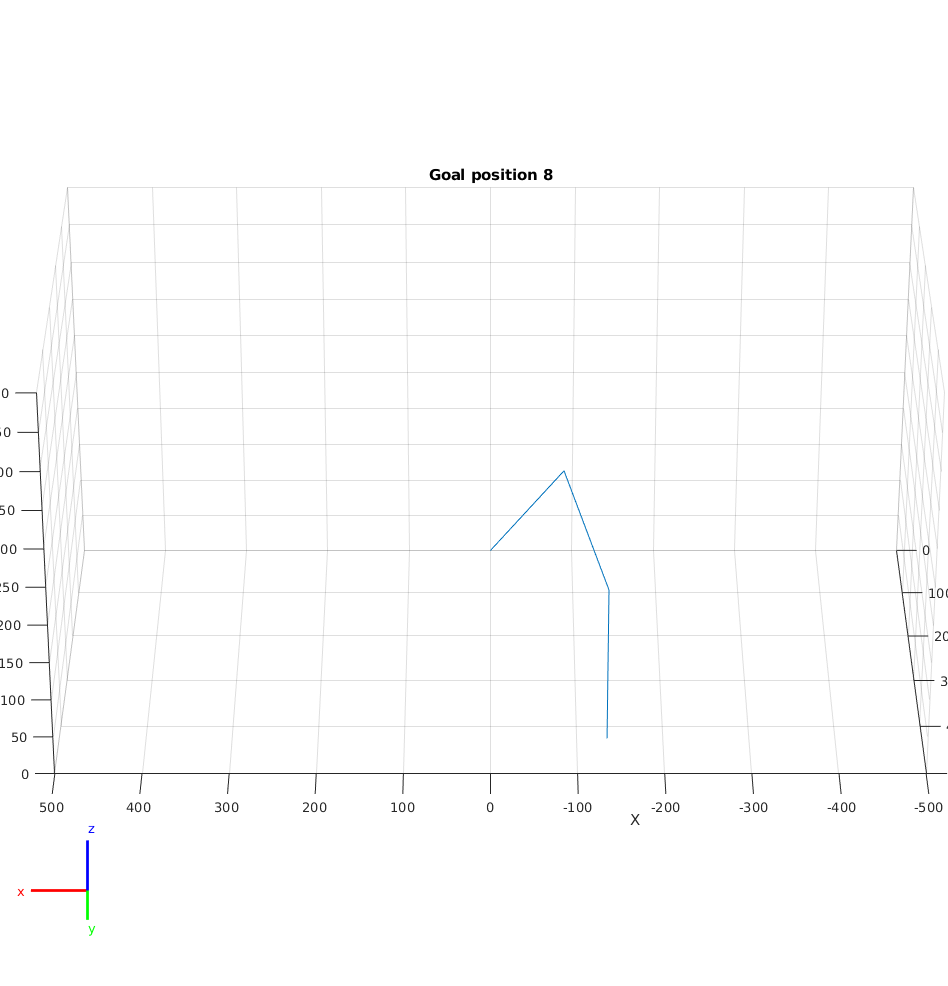

for i = 1:8
    show(denso_robot,goal_pos(:,:,i));
    axis([-500,500,0,500,0,500]) % Set axes to be like video
    view(180,30) % Adjust camera view
    title(sprintf("Goal position %d",i))
    pause(1)
end

### Set Physical Properties

Set masses and moments of inertia.